# 做2016年S&P VaR的预测failure rate，输出到txt

this m_file is used to produce all VaR tables in need

clear, clc
addpath('data_Files'); % add 'data_Files' folder to the search path
load('sampletable.mat');
logRet = sample_table.logRet;
TimeLine = sample_table.TimeLine;
rmpath('data_Files')
ConfidenceLevel=[0.25 0.5 1 2.5 5 7.5 10]*0.01;
FigureVaRIndex=[3,5,7];% use FigureVaRIndex of ConfidenceLevel to figure VaR
outsampleStart = 6806;
outsampleEnd = 7057;
SaveTxtName='results_Files/VaRSP2016_2020220206.txt';
SaveVaRNameSuffix='2016';
SaveRoute='results_Files/';
addpath('results_Files');
addpath('m_Files_KupiecTest');
addpath('m_Files_VaR');

## 历史模拟法与Variance-covariance

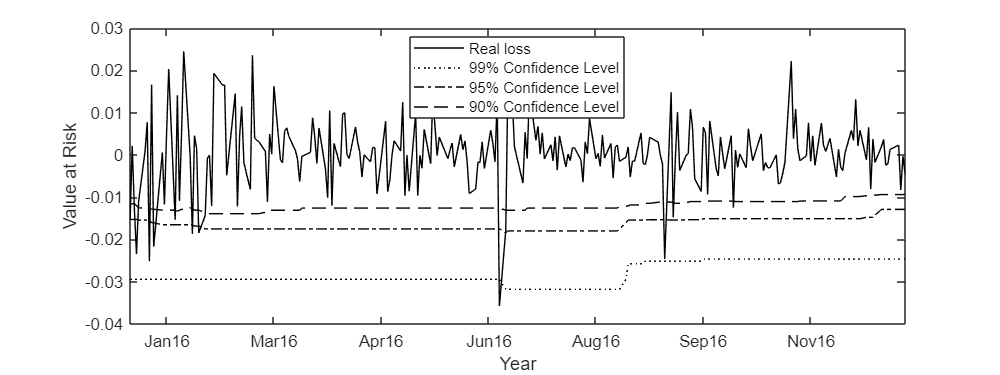

hVaR = zeros(size(logRet(outsampleStart:outsampleEnd),1),7);
pVaR = zeros(size(logRet(outsampleStart:outsampleEnd),1),7);
pVaRT = zeros(size(logRet(outsampleStart:outsampleEnd),1),7);
for i = outsampleStart : outsampleEnd
    %历史模拟法
    confidence = prctile(logRet(i-251:i-1), ConfidenceLevel*100);
    hVaR(i+1-outsampleStart, :) = confidence;
    %Variance-covariance
    pVaR(i+1-outsampleStart, :) = norminv(ConfidenceLevel,mean(logRet(i-251:i-1)),std(logRet(i-251:i-1)));
    %如果VaR中分位数为t分布
    pVaRT(i+1-outsampleStart, :) = tinv(ConfidenceLevel,50)*std(logRet(i-251:i-1))+mean(logRet(i-251:i-1));% 设自由度nu=50
end
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'历史模拟法. \n');fclose(ftxt);
TableOutput=tableVaRPredict(hVaR,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);%历史模拟法
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true)  

ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'Variance-covariance收益率正态分布. \n');fclose(ftxt);
TableOutput=tableVaRPredict(pVaR,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);%Variance-covariance
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true)  

ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'Variance-covariance收益率为t分布. \n');fclose(ftxt);
TableOutput=tableVaRPredict(pVaRT,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);%如果VaR中分位数为t分布
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true)  

figureVaR(hVaR(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));

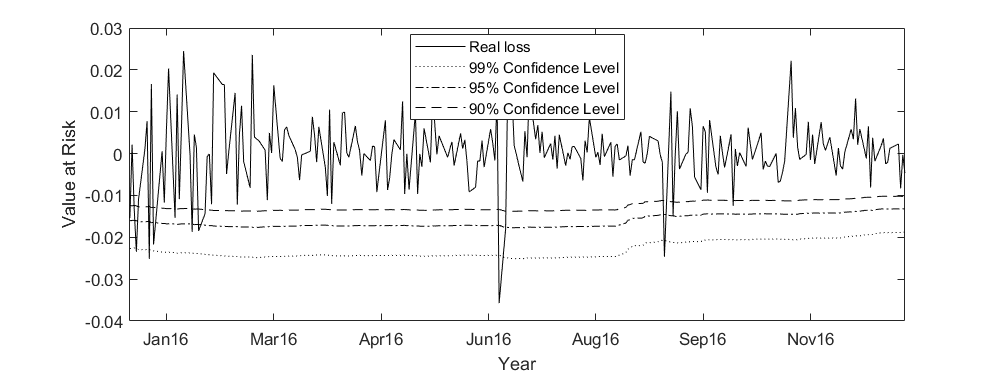

title('历史模拟法')
figureVaR(pVaR(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));

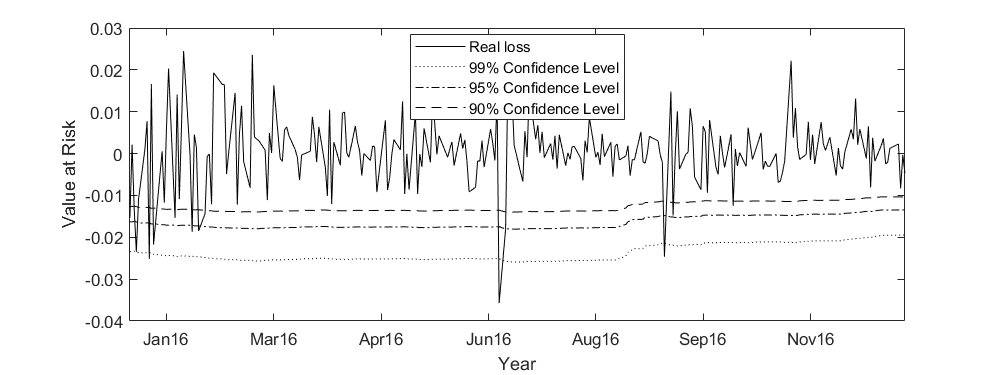

title('Variance-covariance收益率正态分布')
figureVaR(pVaRT(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));

title('Variance-covariance收益率为t分布')
save([SaveRoute 'HSVaR' SaveVaRNameSuffix],'hVaR','logRet','outsampleStart','outsampleEnd');
save([SaveRoute 'VaCovVaR' SaveVaRNameSuffix],'pVaR','pVaRT','logRet','outsampleStart','outsampleEnd');

## GARCH VaR

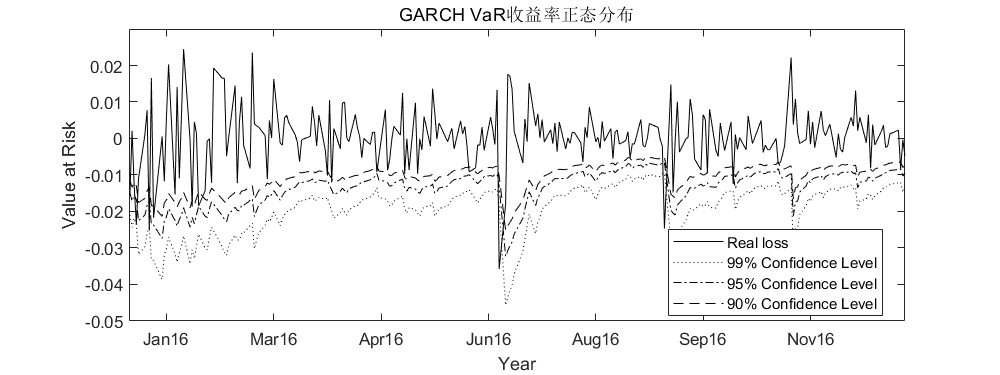

addpath('m_Files_GARCHfamily');
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'GARCH VaR收益率正态分布. \n');fclose(ftxt);
GARCHVaR = GARCHVaRPredict(logRet,outsampleStart,outsampleEnd,250,1,'Normal',ConfidenceLevel);%收益率正态分布
TableOutput=tableVaRPredict(GARCHVaR,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true)  

ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'GARCH VaR收益率T分布. \n');fclose(ftxt);
GARCHVaRT = GARCHVaRPredict(logRet,outsampleStart,outsampleEnd,250,1,'T',ConfidenceLevel);%收益率t分布
TableOutput=tableVaRPredict(GARCHVaRT,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true)  

figureVaR(GARCHVaR(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('GARCH VaR收益率正态分布')

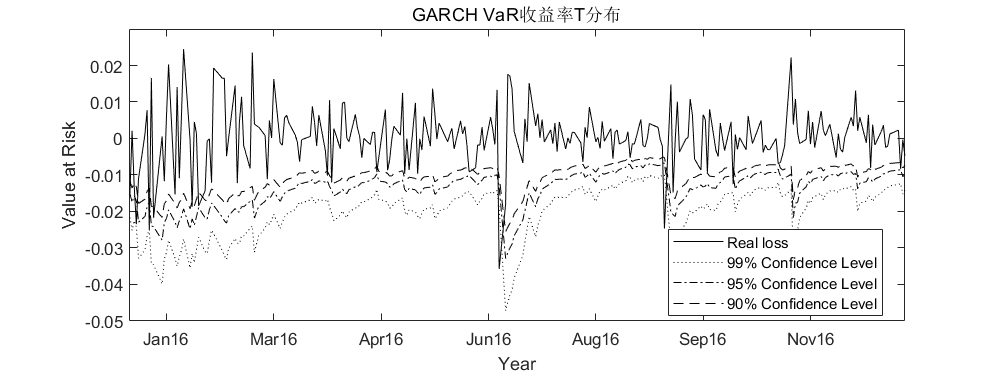

figureVaR(GARCHVaRT(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('GARCH VaR收益率T分布')

save([SaveRoute 'GARCHVaR' SaveVaRNameSuffix],'GARCHVaR','GARCHVaRT','logRet','outsampleStart','outsampleEnd');

## EGARCH VaR (TIME: 1min)

ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'EGARCH VaR收益率正态分布. \n');fclose(ftxt);
EGARCHVaRNorm = EGARCHVaRPredict(logRet,outsampleStart,outsampleEnd,300,1,'Normal',ConfidenceLevel);
TableOutput=tableVaRPredict(EGARCHVaRNorm,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true)  

ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'EGARCH VaR收益率T分布. \n');fclose(ftxt);
EGARCHVaRT = EGARCHVaRPredict(logRet,outsampleStart,outsampleEnd,300,1,'T',ConfidenceLevel);
TableOutput=tableVaRPredict(EGARCHVaRT,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true)  

figureVaR(EGARCHVaRNorm(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('EGARCH VaR收益率正态分布')
figureVaR(EGARCHVaRT(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('EGARCH VaR收益率T分布')

save([SaveRoute 'EGARCHVaR' SaveVaRNameSuffix],'EGARCHVaRT','logRet','outsampleStart','outsampleEnd')
rmpath('m_Files_GARCHfamily');

## Regime Switching GARCH VaR (Haas Model) (TIME: 15min)

ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'RSGARCH VaR收益率正态分布. \n');fclose(ftxt);
RSGARCHVaRNorm = RSGARCHVaRPredict_Haas(logRet,outsampleStart,outsampleEnd,250,1,'Normal',ConfidenceLevel);

____________________________________________________________
   Diagnostic Information

Number of variables: 10

Functions 
Objective:                            @(x)swgarch_likelihood(x,data_augmented,k,error_type,ms_type,T,0)
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
Nonlinear constraints:                @(x)swgarch_constr(x,k)
Nonlinear constraints gradient:       finite-differencing

Constraints
Number of nonlinear inequality constraints: 1
Number of nonlinear equality constraints:   2
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      0
Number of lower bound constraints:          10
Number of upper bound constraints:          0

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f

TableOutput=tableVaRPredict(RSGARCHVaRNorm,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);

ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'RSGARCH VaR收益率T分布. \n');fclose(ftxt);
RSGARCHVaRT = RSGARCHVaRPredict_Haas(logRet,outsampleStart,outsampleEnd,250,1,'T',ConfidenceLevel);

____________________________________________________________
   Diagnostic Information

Number of variables: 11

Functions 
Objective:                            @(x)swgarch_likelihood(x,data_augmented,k,error_type,ms_type,T,0)
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
Nonlinear constraints:                @(x)swgarch_constr(x,k)
Nonlinear constraints gradient:       finite-differencing

Constraints
Number of nonlinear inequality constraints: 1
Number of nonlinear equality constraints:   2
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      0
Number of lower bound constraints:          11
Number of upper bound constraints:          0

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f

TableOutput=tableVaRPredict(RSGARCHVaRT,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);

figureVaR(RSGARCHVaRNorm(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('RSGARCH VaR收益率正态分布')
figureVaR(RSGARCHVaRT(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('RSGARCH VaR收益率T分布')
save([SaveRoute 'RSGARCHVaR' SaveVaRNameSuffix],'RSGARCHVaRNorm','RSGARCHVaRT','logRet','outsampleStart','outsampleEnd')

## GARCH Cluster Partition VaR (TIME: 30min)

addpath('m_Files_ClusterPartition');
addpath('m_Files_GARCHfamily');
[GARCHclusterVaRNorm1,GARCHclusterVaRNorm2] = GARCHclusterVaRPredict(logRet,outsampleStart,outsampleEnd,500,1,'Normal',ConfidenceLevel);
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'GARCH Cluster VaR收益率正态分布，范围取最后一个cluster. \n');fclose(ftxt);
TableOutput=tableVaRPredict(GARCHclusterVaRNorm1,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'GARCH Cluster VaR收益率正态分布，范围取最后一年. \n');fclose(ftxt);
TableOutput=tableVaRPredict(GARCHclusterVaRNorm2,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);

[GARCHclusterVaRT1,GARCHclusterVaRT2] = GARCHclusterVaRPredict(logRet,outsampleStart,outsampleEnd,500,1,'T',ConfidenceLevel);
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'GARCH Cluster VaR收益率T分布，范围取最后一个cluster. \n');fclose(ftxt);
TableOutput=tableVaRPredict(GARCHclusterVaRT1,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'GARCH Cluster VaR收益率T分布，范围取最后一年. \n');fclose(ftxt);
TableOutput=tableVaRPredict(GARCHclusterVaRT2,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);

figureVaR(GARCHclusterVaRNorm1(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('GARCH Cluster VaR收益率正态分布，范围取最后一个cluster')
figureVaR(GARCHclusterVaRNorm2(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('GARCH Cluster VaR收益率正态分布，范围取最后一年')
figureVaR(GARCHclusterVaRT1(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('GARCH Cluster VaR收益率T分布，范围取最后一个cluster')
figureVaR(GARCHclusterVaRT2(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('GARCH Cluster VaR收益率T分布，范围取最后一年')
save([SaveRoute 'GARCHclusterVaR' SaveVaRNameSuffix],'GARCHclusterVaRNorm1','GARCHclusterVaRNorm2','GARCHclusterVaRT1','GARCHclusterVaRT2',...
    'logRet','outsampleStart','outsampleEnd')

## EGARCH Cluster Partition VaR (TIME: 55min)

[EGARCHclusterVaRNorm1,EGARCHclusterVaRNorm2] = EGARCHclusterVaRPredict(logRet,outsampleStart,outsampleEnd,500,1,'Normal',ConfidenceLevel);
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'EGARCH Cluster VaR收益率正态分布，范围取最后一个cluster. \n');fclose(ftxt);
TableOutput=tableVaRPredict(EGARCHclusterVaRNorm1,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'EGARCH Cluster VaR收益率正态分布，范围取最后一年. \n');fclose(ftxt);
TableOutput=tableVaRPredict(EGARCHclusterVaRNorm2,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);

[EGARCHclusterVaRT1,EGARCHclusterVaRT2] = EGARCHclusterVaRPredict(logRet,outsampleStart,outsampleEnd,500,1,'T',ConfidenceLevel);
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'EGARCH Cluster VaR收益率T分布，范围取最后一个cluster. \n');fclose(ftxt);
TableOutput=tableVaRPredict(EGARCHclusterVaRT1,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);
ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'EGARCH Cluster VaR收益率T分布，范围取最后一年. \n');fclose(ftxt);
TableMatrix=tableVaRPredict(EGARCHclusterVaRT2,logRet,outsampleStart,outsampleEnd,ConfidenceLevel);
writetable(TableOutput,SaveTxtName,'WriteMode','Append','WriteVariableNames',true,'WriteRowNames',true);

figureVaR(EGARCHclusterVaRNorm1(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('EGARCH Cluster VaR收益率正态分布，范围取最后一个cluster')
figureVaR(EGARCHclusterVaRNorm2(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('EGARCH Cluster VaR收益率正态分布，范围取最后一年')
figureVaR(EGARCHclusterVaRT1(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('EGARCH Cluster VaR收益率T分布，范围取最后一个cluster')
figureVaR(EGARCHclusterVaRT2(:,FigureVaRIndex),logRet(outsampleStart:outsampleEnd),TimeLine(outsampleStart:outsampleEnd));
title('EGARCH Cluster VaR收益率T分布，范围取最后一年')
rmpath('m_Files_ClusterPartition');
save([SaveRoute 'EGARCHclusterVaR' SaveVaRNameSuffix],'EGARCHclusterVaRNorm1','EGARCHclusterVaRNorm2','EGARCHclusterVaRT1','EGARCHclusterVaRT2','logRet','outsampleStart','outsampleEnd')
rmpath('m_Files_VaR');
rmpath('m_Files_KupiecTest');
rmpath('m_Files_GARCHfamily');